fft_output = importdata('fft_output_6.txt');

real_part = fft_output.data(:,1);
imag_part = fft_output.data(:,2);
fixed16_real = fft_output.data(:,3);
fixed16_imag = fft_output.data(:,4);

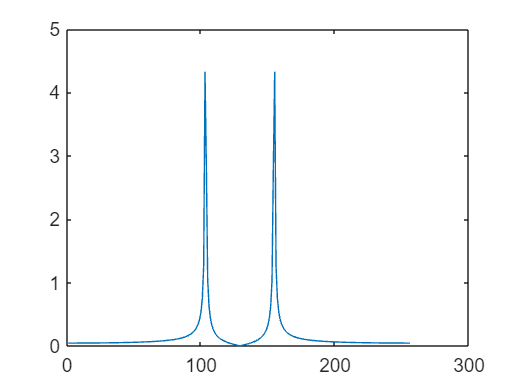

s = real_part + i*imag_part;
fix_s = fixed16_real + i*fixed16_imag;
x = 1:length(s);
plot(x,fftshift(abs(s)))

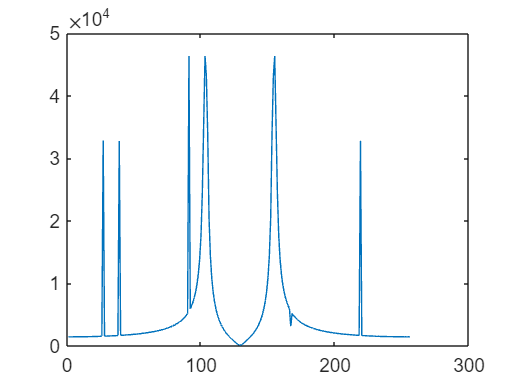

plot(x,fftshift(abs(fix_s)))

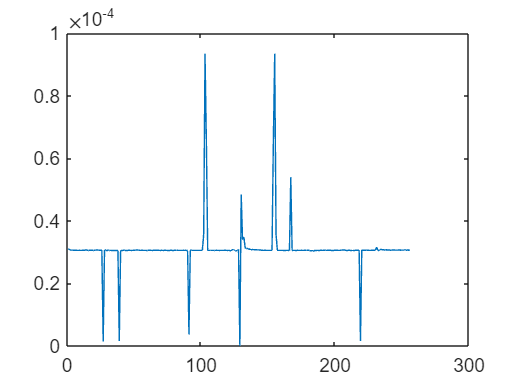

plot(x,fftshift(abs(s ./ fix_s)))

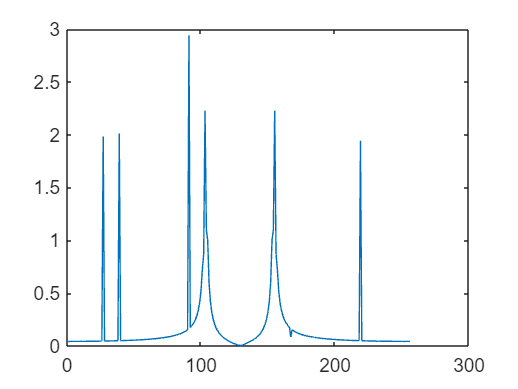

plot(x,fftshift(abs(s - 6e-5 * fix_s)))